# Modelling glycogen storage and consumption during the diurnal cycle

This live script runs a comets simulation mimicing the environment used in wet lab experiments with *Prochlorococcus marins* MED4. The experimental data is from David Sher's lab, more precisely from Grossowic et al., 2017.

% Init cobra toolbox
initCobraToolbox;

% Define simulation parameters
% In general we use conditions from Grossowicz et al. 
% Initial population in Grossowizc is 1.3e9 cells/L
grid_size = 1; %cm
grid_volume_cm3 = grid_size^3; %Cubic centimeters
grid_volume = grid_volume_cm3*1e-3; % Convert from cubic centimeters to L
cell_weight = 66*1e-15;  % g per cell (Cermak et al., 2017)
initial_pop = 1.3e9*cell_weight*grid_volume;

timeStep = 0.1;% hours
maxCycles = 24*4/timeStep; % Simulate 4 days
lightFlux = 0.04;
glycVmax = 0.5;
glycKm = 1e-7;
AmmoniumConc = 800;
CO2MAX =  0.818; % From environmental sampling
HCO3MAX = 18.43;

Load Prochlorococcus Genome-scale model

model_fn = '..\..\Model_files\iSO595v6.mat';
model = readCbModel(model_fn);
model = setBiomassRxn(model, 'BIOMASS');
folder = [pwd '\simulations'];

## Set reaction bounds

%printRxnFormula(model, 'GlycogenEX')
glycogen_index = find(strcmp(model.rxns, 'GlycogenEX'));
model.lb(glycogen_index) = -1000;
model.ub(glycogen_index) = 1000;

%ATPM_index = find(strcmp(model.rxns, 'Maintenance'));
CO2EX_index = find(strcmp(model.rxns, 'CO2EX'));
model.lb(CO2EX_index) = 0;
model.ub(CO2EX_index) = CO2MAX;

HCO3EX_index = find(strcmp(model.rxns, 'HCO3EXcar'));
model.lb(HCO3EX_index) = -HCO3MAX;
model.ub(HCO3EX_index) = 0;

Define kinetic parameters Use optimal Vmax and Km from Figure 3

ammonium_Km = 0.39;
ammonium_Vmax = 0.9;
model = setVmax(model, 'AmmoniaEX', ammonium_Vmax);% mmol/gDW/h
model = setKm(model, 'AmmoniaEX', ammonium_Km*1e-3);% Converting from mM to mmol/cm^3 is used in
model = setVmax(model, 'HCO3EXcar', HCO3MAX); % Default value
model = setKm(model, 'HCO3EXcar', 0.082*1e-3); % From Hopkinson et al., 2014
model = setVmax(model, 'FAKEOrthophosphateEX', 0.7575); % From Krumhardt et al., 2013
model = setKm(model, 'FAKEOrthophosphateEX', 0.00053*1e-3); % From Krumhardt et al., 2013
model = setKm(model, 'GlycogenEX', glycKm);
model = setVmax(model, 'GlycogenEX', glycVmax);

% Define model light settings
% In the following we assume that the light source is monochromatic at 680nm, 
% however it is possible to extend the following calculations to a wave-length 
% dependent light-source.  
% 
% It is necessary to calculate a model-specific weight-specific absorption rate, 
% this is achieved by using  the derived pigment absorption spectra provided by 
% Bricaud et al., 2004. The calculations follows the methods in Bricaud et al., 
% 2004, as originally described in Moreal and Bricaud, 1981. 
% 
% 
% Define variables such as pigment concentrations in _Prochlorococcus,_ absorption coefficients and refraction index  
% At 680nm we can ignore absorption by other pigments than divinyl chlorophyll 
% a and b.

% The ratio of chlorophyll is extracted from the model biomass-function
ci_dvchla = 0.028*0.581196581; % g / gDW (Partensky 1993 / Casey 2016)
ci_dvchlb = 0.028*0.047008547; % g / gDW (Partensky 1993 / Casey 2016)
absorption_dvchla_680 = 0.018358; % m2 mg-1 (Bricaud et al., 2004)
absorption_dvchlb_680 = 0.0018;   % m2 mg-1 (Bricaud et al., 2004)
absorption_water_680 = 0.465; % m^-1 (Pope and Fry, 1997)
wavelength = 680;% nm
diameter = 0.6; % um 
n_dash = 13.77*1e-3; % imaginary part of refractive index at 675 nm, from Stramski et al

% Calculate the packaging effect
% This is taking into account that the light-aborsbing pigments are not dissolved 
% in the media, but contained with in discrete cells. See Moreail and Bricaud, 
% 1981, for a thorough explanation. 

% Calculate the packaging effect index Q* 
size_parameter_alpha = diameter*1e3*pi/wavelength;
rho_dash = 4*size_parameter_alpha*n_dash;
Q_a = 1+(2*exp(-rho_dash)/rho_dash)+2*(exp(-rho_dash)-1)/rho_dash^2;
packaging_effect = 1.5*Q_a/rho_dash;
% Calculate the weight-specific absorption coefficient 

% This coefficient is in units m^2/ g DW biomass
% Multiply by 1e3 to convert from g to mg
absorption_biomass = packaging_effect*(ci_dvchla*1e3*absorption_dvchla_680+ci_dvchlb*1e3*absorption_dvchlb_680);

% Set the calculated absorption rate as a model parameter for the exchange reaction of light

absorption_matrix = zeros(1,2);
absorption_matrix(1) = absorption_water_680;
absorption_matrix(2) = absorption_biomass;
model  = setLight(model, {'LightEX'}, absorption_matrix);

Make folder and define filenames

folder = [folder '\' sprintf('N%d', AmmoniumConc) '_' sprintf('light_%0.2f', lightFlux) '_' sprintf('glycVmax_%0.2f', glycVmax) '_' sprintf('glycKm_%0.0e', glycKm) '_' sprintf('HCO3MAX_%0.0f', HCO3MAX)];
if ~exist(folder,'dir')
    mkdir(folder);
end

fluxLogfn = 'fluxLog.csv';
biomassLogfn = 'biomassLog.csv';
mediaLogfn = 'mediaLog.csv';
model.description = 'iSO595v6';
layout_name = 'layout.txt';

% Creat layout
layout = CometsLayout();
layout = layout.addModel(model);
layout = setInitialPop(layout, '1x1', initial_pop); % g DW

% Set simulation parameters

layout.params.mediaLogName = [folder '\' mediaLogfn];
layout.params.writeMediaLog = true;
layout.params.mediaLogRate = 1;
layout.params.biomassLogName = [folder '\' biomassLogfn];
layout.params.writeBiomassLog = false;
layout.params.biomassLogRate = 1;

% Write fluxes
layout.params.fluxLogName =  [folder '\' fluxLogfn];
layout.params.writeFluxLog = true;
layout.params.fluxLogRate = 1;


layout.params.maxCycles = maxCycles;
layout.params.timeStep = timeStep; %Hours
layout.params.spaceWidth = 1; % Centimeters (0.1 is default value)
layout.params.maxSpaceBiomass = 100000;
layout.params.defaultDiffConst = 0;
layout.params.objectiveStyle = 'MAX_OBJECTIVE_MIN_TOTAL';
layout.params.deathRate = 0.1/24; % Per hour. From Grossowicz (they reference William and Follows, 2011)

%put a timestep
layout.params.useLogNameTimeStamp=false;
layout.params.fluxLogFormat = 'COMETS';
layout.params.mediaLogFormat = 'COMETS';
layout.params.biomassLogFormat = 'COMETS';
% Define medium as PRO99, with modifications in Grossowicz, 2017
% Defined in Moore et al., 2007

% Define medium in uM
pro99_media = struct('ammonia', AmmoniumConc, ... % 100 Grossowizc, 800 uM in PRO99
                     'bicarbonate', 3000, ... % uM 
                     'phosphate', 50);

% Calculate values in mmol and set to layout
grid_volume = layout.params.spaceWidth^3*1e-3; % In cubic decimetermeter aka liters
layout = layout.setMedia('Ammonia[e]', pro99_media.ammonia*1e-3*grid_volume); % in mmol
layout = layout.setMedia('HCO3[e]', pro99_media.bicarbonate*1e-3*grid_volume); % in mmol
layout = layout.setMedia('Orthophosphate[e]', pro99_media.phosphate*1e-3*grid_volume); % in mmol

## Set light conditions

%Set  a sinus distribution of photons
layout = layout.setGlobalPeriodicMedia('Photon[e]', "half_sin", lightFlux, 24,0,0);
% Define salts and mineral needed for growth
% Set to maximum value to ensure these compounds are not limiting growth in 
% any way

layout = layout.setMedia('H[e]', 1000);
%layout = layout.setMedia('Orthophosphate[e]', 1000); 
layout = layout.setMedia('H2O[e]', 1000);
layout = layout.setMedia('Oxygen[e]', 1000);    
layout = layout.setMedia('Cadmium[e]', 1000);
layout = layout.setMedia('Calcium_cation[e]', 1000);
layout = layout.setMedia('Chloride_ion[e]', 1000);
layout = layout.setMedia('Cobalt_ion[e]', 1000);
layout = layout.setMedia('Copper[e]', 1000);

layout = layout.setMedia('Fe2[e]', 1000);
layout = layout.setMedia('Magnesium_cation[e]', 1000);
layout = layout.setMedia('Molybdenum[e]', 1000);
layout = layout.setMedia('K[e]', 1000);
layout = layout.setMedia('Selenate[e]', 1000);
layout = layout.setMedia('Sodium_cation[e]', 1000);
layout = layout.setMedia('Strontium_cation[e]', 1000);
layout = layout.setMedia('Sulfate[e]', 1000);
layout = layout.setMedia('Zn2[e]', 1000);
layout = layout.setMedia('Glycogen[e]', 0.0000);
%layout = layout.setMedia('Hydrogen_sulfide[e]',1000);
    
    
% Set multilevel objective to ensure glycogen production

photonUptakeIndex = find(strcmp(layout.models{1,1}.rxns, 'LightEX'));
biomassIndex = find(strcmp(layout.models{1,1}.rxns, 'BIOMASS'));
hco3_index = find(strcmp(layout.models{1,1}.rxns, 'HCO3EXcar'));
glycogen_index = find(strcmp(layout.models{1,1}.rxns, 'GlycogenEX'));
ATPM_index = find(strcmp(layout.models{1,1}.rxns, 'Maintenance'));
phosphate_index = find(strcmp(layout.models{1,1}.rxns, 'FAKEOrthophosphateEX'));


layout.models{1,1}.lb(ATPM_index) = 0;
layout.models{1,1}.c(ATPM_index) = 1;
%layout.models{1,1}.c(photonUptakeIndex) = -4;
%layout.models{1,1}.c(hco3_index) = -5;
layout.models{1,1}.c(biomassIndex) = 2;
layout.models{1,1}.c(glycogen_index) = 3;

%model.lb(biomassIndex) = 1e-5;
% Write layout
createCometsFiles(layout, folder, layout_name);

runCometsOnDirectory(folder)

ans =     '
     C:\Users\snorres\git\Prochlorococcus_Model\COMETS_files\diurnal_cycle\simulations\N100_light_0.04_glycVmax_0.50_glycKm_1e-07_HCO3MAX_18>java -Xmx2048m -classpath C:\Users\snorres\cometsS/comets.jar;C:\Users\snorres\cometsS/bin/comets.jar;C:\Users\snorres\cometsS/lib/glpk-java.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/jogl-all.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/gluegen.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/gluegen-rt.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/gluegen-rt-natives-windows-amd64.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/jogl-all-natives-windows-amd64.jar;C:\Users\snorres\cometsS/lib/jmatio.jar;C:\Users\snorres\cometsS/lib/jamtio.jar;C:\gurobi811\win64/lib/gurobi.jar -Djava.library.path=C:\Users\snorres\cometsS/;C:\Users\snorres\cometsS/lib/;C:\gurobi811\win64/lib/;C:\gurobi811\win64/bin edu.bu.segrelab.comets.Comets -loader edu.bu.segrelab.comets.fba.FBACometsLoader -s

cd('../..');

## Plot results

% Load experimental data
%hold on;

media = parseMediaLog([folder '\' mediaLogfn]);

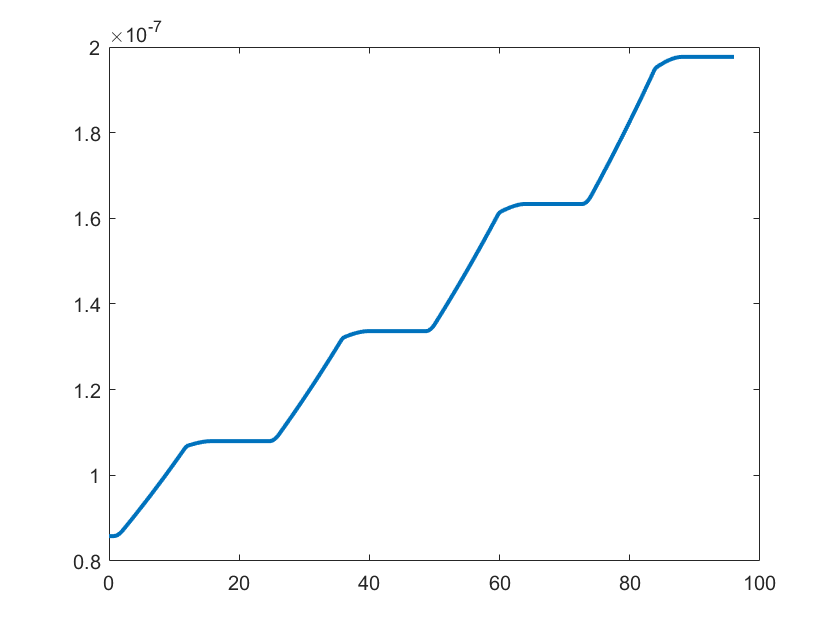

%converting from biomass (g DW) to number of cells
f = figure();
biomass_table = media(strcmp('biomass[e]', media.metname),:);
time = biomass_table.t*timeStep;
plot(time, biomass_table.amt+initial_pop, 'DisplayName', 'Predicted growth', 'LineWidth',2);
saveas(f, [folder '\Growth.png'])

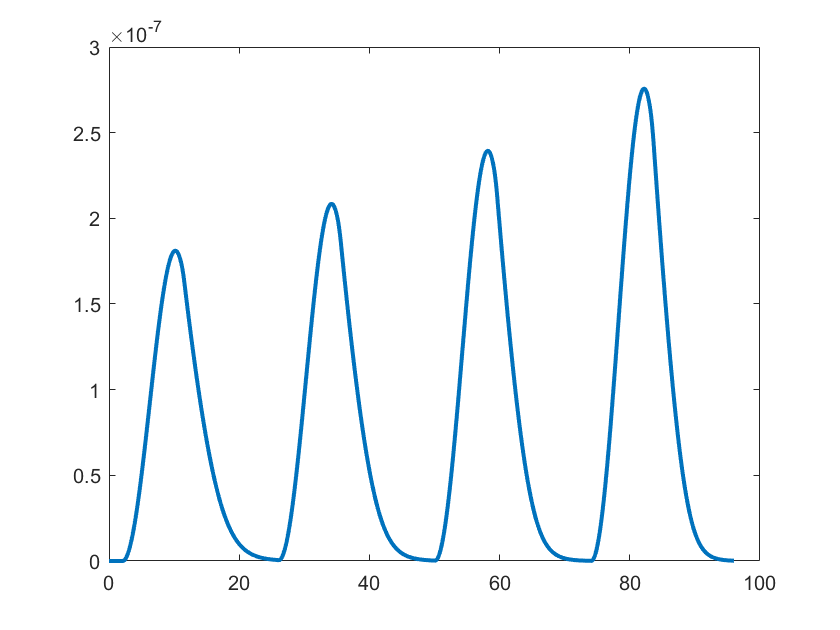

f = figure();
glycogen = media(strcmp('Glycogen[e]', media.metname),:);
plot(time, glycogen.amt, 'DisplayName', 'Glycogen', 'LineWidth',2);
saveas(f, [folder '\Glycogen.png'])

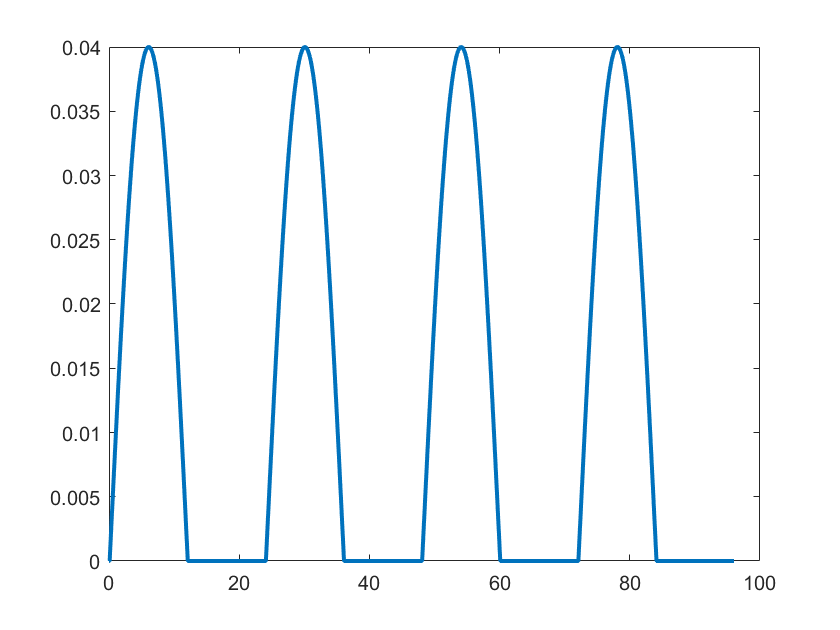


f = figure();
photon = media(strcmp('Photon[e]', media.metname),:);
plot(time, photon.amt, 'DisplayName', 'Photon', 'LineWidth',2);
saveas(f, [folder '\Light.png'])

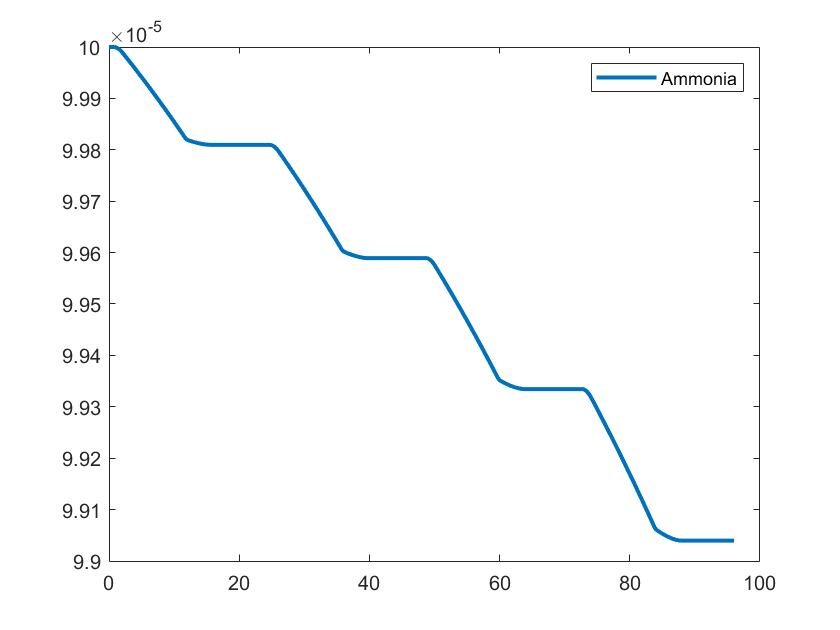

Ammonia = media(strcmp('Ammonia[e]', media.metname),:);
plot(time, Ammonia.amt, 'DisplayName', 'Ammonia', 'LineWidth',2);
legend()

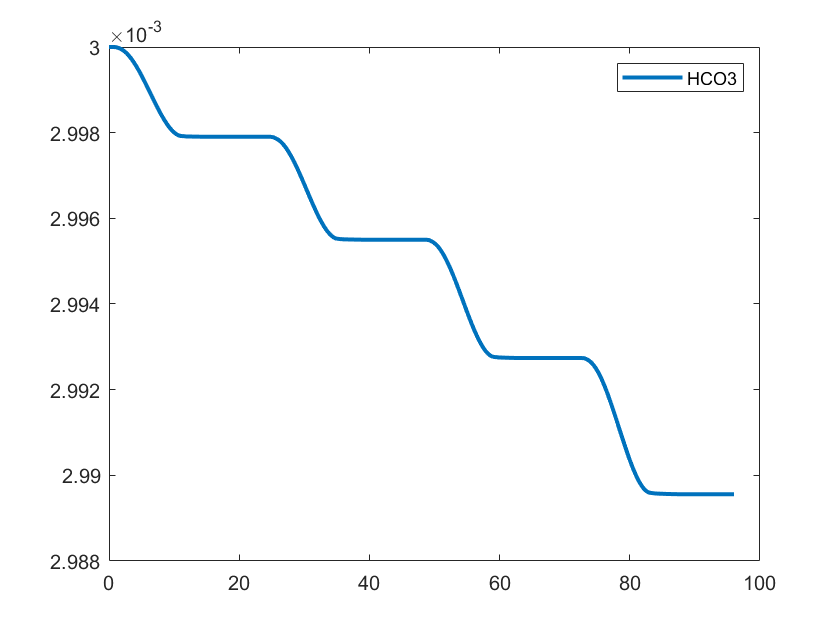


f = figure();
hco3 = media(strcmp('HCO3[e]', media.metname),:);
plot(time, hco3.amt, 'DisplayName', 'HCO3', 'LineWidth',2);
legend()

%hold on;

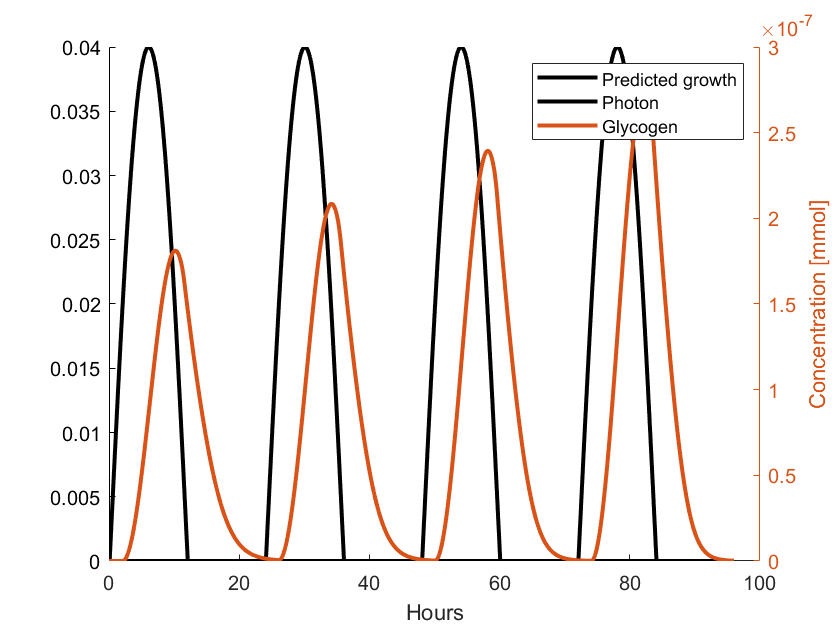

f = figure();
hold on;
plot(time, biomass_table.amt+initial_pop, 'DisplayName', 'Predicted growth', 'LineWidth',2);
yyaxis left;
plot(time, photon.amt, 'DisplayName', 'Photon', 'LineWidth',2);
%plot(time, Ammonia.amt, 'DisplayName', 'Ammonia', 'LineWidth',2);
yyaxis right;
plot(time, glycogen.amt, 'DisplayName', 'Glycogen', 'LineWidth',2);
legend()
xlabel("Hours")
ylabel('Concentration [mmol]')

results_table = table(biomass_table.t*timeStep, biomass_table.amt+initial_pop,glycogen.amt,photon.amt,hco3.amt, 'VariableNames', {'Time','Biomass','Glycogen', 'Photon', 'HCO3'});
writetable(results_table, [folder '\' 'results_table.csv']);

flux = parseFluxLog([folder '\' fluxLogfn]);

writecell(layout.models{1,1}.rxns, [folder '\' 'rxnIDs.csv']);

writetable(flux, [folder '\' 'fluxTable.csv'])
writetable(media, [folder '\' 'mediaTable.csv'])